# `Performance Testing / Characterization Script`

Read in JSON File for simulation configuration

clear;

david_file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/";
kristen_file_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
json_text = fileread(david_file_path + "test_config.json");
sim_config = jsondecode(json_text);

Setup parameters from JSON file 

NUM_RUNS = sim_config.TestSettings.Configurations.num_runs;
FRAMES_PER_RUN = sim_config.TestSettings.Configurations.frames_per_sim;
PRE_ATTACK_FRAMES = sim_config.TestSettings.Configurations.pre_attack_frames;
MAX_BIN = sim_config.TestSettings.Configurations.max_bin;

TOTAL_FRAMES = NUM_RUNS * (FRAMES_PER_RUN-PRE_ATTACK_FRAMES);

Progress bar initialization

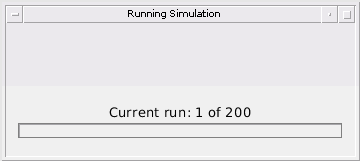

status = sprintf("Current run: %d of %d",1, NUM_RUNS);
progress_bar = waitbar(0,status,"Name","Running Simulation");

Declare the simulation

sim = Simulation_reconfigurable();

'Simulation_reconfigurable' is not found in the current folder or on the MATLAB path, but exists in:
    /home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model

Change the MATLAB current folder or add its folder to the MATLAB path.

values = zeros(0,0);

Run simulation for NUM_RUNS, each time with different configuration

for run_idx = 1: NUM_RUNS
    status = sprintf("Current run: %d or %d",run_idx, NUM_RUNS);
    waitbar(run_idx/NUM_RUNS,progress_bar,status);

    target_velocity = sign(randn) * randi(35)
    target_start = randi(138)+ 5;
    sim.initialize_simulation(sim_config, target_start, target_velocity);
    
    sim.run_simulation();

    [detected, actual_ranges, estimated_ranges, estimated_velocities, actual_velocities, percent_error_ranges, percent_error_velocities, false_positives] = sim.simulation_results();

    values = [values; actual_ranges(PRE_ATTACK_FRAMES+1:end)', actual_velocities(PRE_ATTACK_FRAMES+1:end)', detected(PRE_ATTACK_FRAMES+1:end,1), estimated_ranges(PRE_ATTACK_FRAMES+1:end,1), percent_error_ranges(PRE_ATTACK_FRAMES+1:end,1), estimated_velocities(PRE_ATTACK_FRAMES+1:end,1), percent_error_velocities(PRE_ATTACK_FRAMES+1:end,1), false_positives(PRE_ATTACK_FRAMES+1:end,1)];
end

Organize data into table

bin_classification = cast(values(:,1)/10, "int16")';
table_data = array2table(values,"VariableNames",["Range (m)","Velocity (m/s)","Detected","Estimated Range (m)", "Error Range (m)", "Estimated Velocity (m/s)", "Error Velocity (m)", "False Positives"]);

Plot P(detection) and P(false positive) vs. Range

histogram_vals = zeros(MAX_BIN,3);

for bin_num = 1:MAX_BIN
    histogram_vals(bin_num, 1) = bin_num;
    count = 0;
    detected = 0;
    false_pos = 0;
    for frame = 1: TOTAL_FRAMES
        if (bin_classification(frame) == bin_num)
            count = count + 1;
            if values(frame, 3)
                detected = detected + 1;
            end
            if values(frame, 8)
                false_pos = false_pos + 1;
            end
        end
    end
    if (count ~= 0)
        histogram_vals(bin_num, 2) = detected/count;
        histogram_vals(bin_num, 3) = false_pos/count;
    end
end

figure
plot(histogram_vals(:,1)*10, histogram_vals(:,2), 'b');
hold on
plot(histogram_vals(:,1)*10, histogram_vals(:,3), '--.g');
hold off
ylabel("P(detection)")
xlabel("Range Bin (m)")
legend("Percent Correct Detection", "Percent False Positives")
title("P(detection) and P(false positives) at Various Target Ranges")

Plot Error vs. Range

%% Error vs Range
range_error_plot = zeros(0,0);
for frame = 1: TOTAL_FRAMES
    if (values(frame, 3) ~= 0)
        range_error_plot = [range_error_plot; [values(frame, 1), values(frame, 5)]];
    end
end
figure
scatter(range_error_plot(:,1), range_error_plot(:,2))
ylabel("Range Error (m)")
xlabel("Range (m)")
title("Range Error at Various Distances")